CODE ADDITIONS 

7/8/2026; 7:53 pm (Isaac)

- Implemented an image processing algorithm that (mostly) works for Tube images. It needs testing.

7/9/2026; 4:34 pm (Ryan)

- Updated Dataset organization so that each subfolders organization matches. Changed to imageDatastore and added class labels and pass/fail classification for each image.

7/11/2026; 4:14 pm (Ryan)

- Added corner removal to improve output decision reliability. Added comments to better explain which image is which when selected from the range (Tubes only).

7/12/2026; 10:52 am (Ryan)

- Added labels to ROI that correspond to each table entry for easier analysis of performance. Adjusted minimum eccentricity to improve detection of short tubes as anomalous.

Choose Data Subset of Interest

dataSubset = "tubes";
displayOrginalImage = true;

Current working algorithm

numObsPerClass = 4×2 table
         Label          Count
    ________________    _____

    color_mismatch         8 
    defective_length      13 
    good                 154 
    malformed_metal       50 


Number of Files: 225


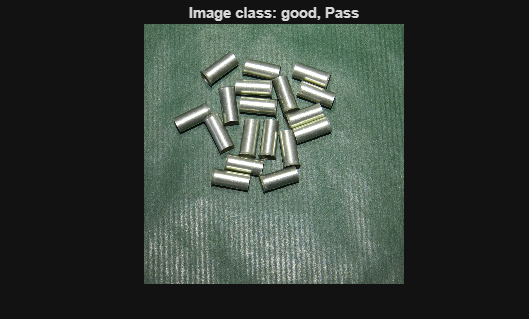

% Obtain the file location of the dataset. 
% ***IMPORTANT***
% This file location stored is a RELATIVE path!!!
% For this script to run, your active path must be set to where
% the MPDD dataset is stored on your local system.
%
% To change your active path, click the "Set Path" option under the
% "Environment" sub tab within the MATLAB application. 
fileLoc = sprintf("MPDD/%s", dataSubset);


% Creates an image Datastore to store all images of specified subset type.
% The image Datastore is setup to specifically look for images with certain file
% extensions that are common for images (i.e. jpg, png, etc.)
ds = imageDatastore(fileLoc, 'IncludeSubfolders',true, 'LabelSource','foldernames', ...
    'FileExtensions', ["*.jpg", "*.png", "*.tiff"]);

% Filter 'ground truth'/masks that are only used for model verification
excludeMask = contains(ds.Files, "gt*" | "mask");
ds = subset(ds, ~excludeMask);

% Obtain the number of files within the selected sub directory
numFiles = numel(ds.Files);

% ***Image processing begins here***
%
% Load the image of interest from the datastore object
% Color mismatch    01 - 008, + 21
% Defective Length  09 - 021
% Malformed Metal   22 - 071, + 8
% Good              72 - 225
imgNum = 197;
img = readimage(ds, imgNum);

% Labels image and (Optionally) Displays class & image info
% imgClass <-- Official label of the image
% imgPF <-- Whether or not the part would pass or fail
imgClass =  ds.Labels(imgNum); 
if imgClass ~= "good"
    imgPF = "Fail"; 
else
    imgPF = "Pass";
end

if displayOrginalImage
    numObsPerClass = countEachLabel(ds)
    imgInfo = sprintf("Image class: %s, %s", imgClass, imgPF);

    disp("Number of Files: " + numFiles);
    imshow(img);
    title(imgInfo);
end

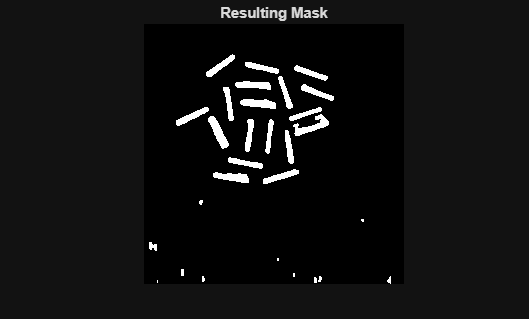

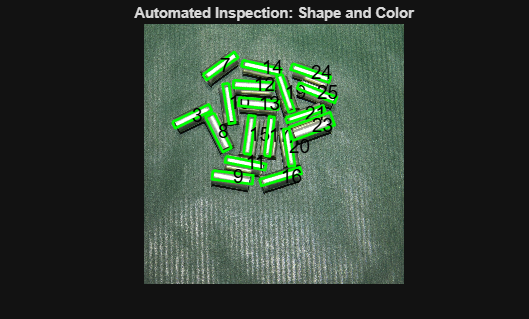

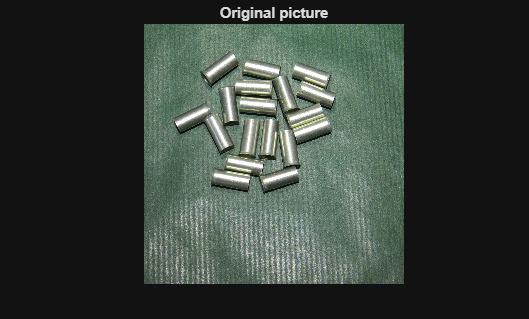


--- Inspection Report ---
Total Tubes Found:  18
Normal Tubes:       18
Shape Anomalies:    0
Color Anomalies:    0
-------------------------

Average Tube Area:      1979.35
Average Tube Eccentricity: 0.89

    Area        Centroid        MajorAxisLength    MinorAxisLength    Eccentricity    Orientation    Num
    ____    ________________    _______________    _______________    ____________    ___________    ___

     751    36.378    877.29        43.037             27.272           0.77359         -39.252       1 
      50     52.36    1014.5        14.802             4.5144           0.95236              90       2 
    3310    189.68    364.21         159.4             27.179           0.98536          25.728       3 
     300    152.76    978.5


% Inspect the image and print out a report
singleImageInspectionFunction(img);